# 'streamline' method usage example

Common setup for all examples

ex_setup

Setup complete


#### Start timer

tic

#### Povlab object

pl = povlab( povray_version,...
             povray_path, ...
             povray_out_dir);

#### Scene

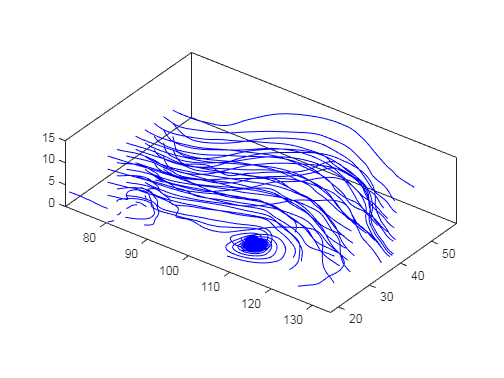

pl.scene_begin('scene_file', 'coneplot.pov', 'image_file', 'coneplot.png');
    pl.include("shapes");    
    pl.include("glass");
    
    pl.global_settings("assumed_gamma 1");
    
    % Camera
    pl.camera('angle', 48, 'location', [140 110 45], 'look_at', [105 37 1], 'type', 'perspective');
    
    % Lights
    pl.light('location', [130 105 80], 'color', [4 4 4], 'shadowless', true);    
    pl.light('location', [70 70 20],   'color', [10 10 10], 'shadowless', true);
    pl.light('location', [70 70 -20],  'color', [10 10 10], 'shadowless', true);

    % Wind for streams
    load wind u v w x y z
    [m,n,p] = size(u);
    
    % Bounding box
    tex =  pl.declare("tex_green", pl.texture('base', 'Silver1', 'pigment_odd', [0.1 0.1 0.1], 'pigment_even', [0.2 0.2 0],   'finish', "phong 1 reflection {0.3 metallic 0.8}"));
    pl.wire_box('llf_corner', [80 15 0], 'urb_corner', [135 60 16], 'radius', 0.2, 'texture', tex);
    
    % Streamline
    [sx,sy,sz] = meshgrid(80, 0:3:n, 0:3:p);

    sl = streamline(x,y,z, u,v,w, sx,sy,sz);
    pl.streamline('data', sl);
    
    % Display preview
    axis tight equal
    view(37,32)
    box on
    colormap(hsv)
    light

pl.scene_end();

#### Rendering and display

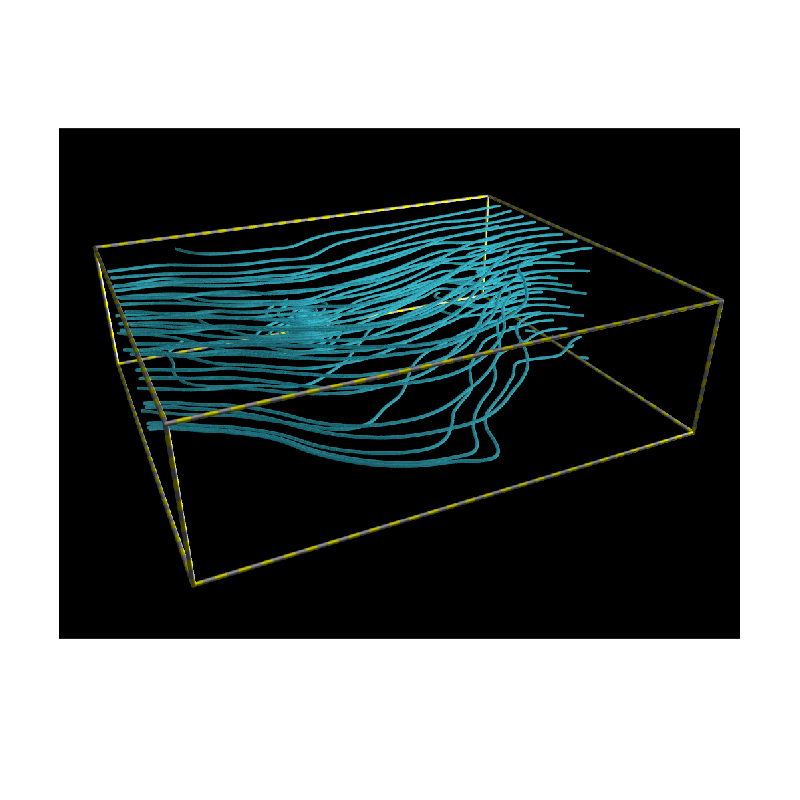

img = pl.render();
imshow(img);

#### Elapsed time

toc

Elapsed time is 317.543298 seconds.
